# **Design Low-pass filter using Parks–McClellan algorithm :**

clear all;

## Enter the desired filter output requirements :

#### Ripple in Passband (Optimized till 0.001) :

Rp = 0.001;

#### Ripple in Stopband (Optimized till 0.001) :

Rs = 0.001;

#### Passband Frequency :

Wp = 0.45;

#### Stopband Frequency :

Ws = 0.55;

#### Sampling Frequency :

Fs = 2;

#### [ Note : The minimum difference between the normalized passband and stopband frequency should be 0.1 ]

## **Parks–McClellan algorithm :**

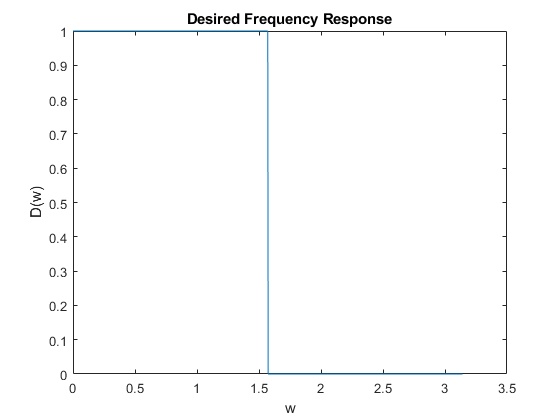

eval_grid = 0:0.001:1;
w_grid = linspace(0,pi,1001);

Wp_i = Wp*2/Fs;
Ws_i = Ws*2/Fs;
Wc_i = (Wp_i + Ws_i)/2;
D_eval = (eval_grid <= Wc_i);
plot(w_grid,D_eval);
xlabel("w");
ylabel("D(w)");
title("Desired Frequency Response")

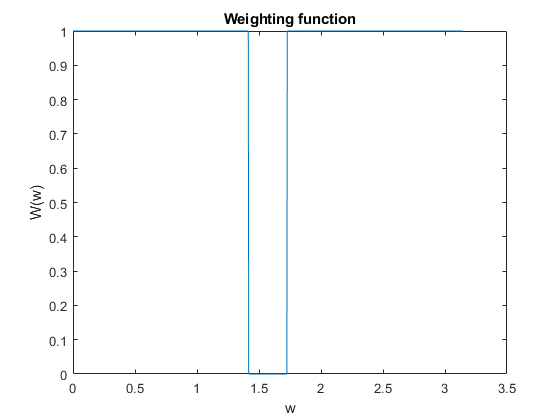

W_eval = (eval_grid <= Wp_i) + ((eval_grid >= Ws_i)*Rp/Rs);
plot(w_grid,W_eval);
xlabel("w");
ylabel("W(w)");
title("Weighting function")

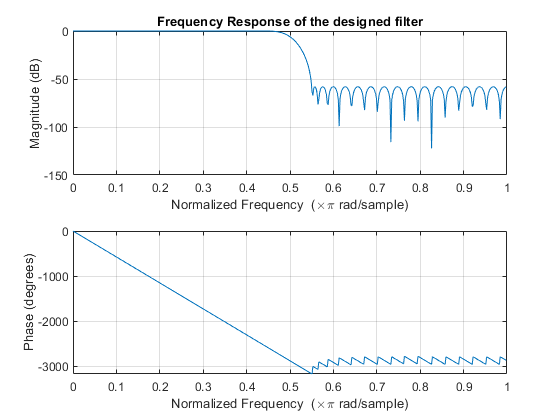

[n,fo,ao,W] = firpmord([Wp Ws],[1 0],[Rp Rs],Fs);

b = firpm(n,fo,ao,W);

M = (n - 1)/2;
R = M + 2;

Np_i = round(Wp_i*R/(Wp_i + 1 - Ws_i));
Ns_i = R - Np_i;

minmax_i = [linspace(0,Wp_i,Np_i) , linspace(Ws_i,1,Ns_i)];

while true
    W = (minmax_i <= Wp_i) + ((minmax_i >= Ws_i)*Rp/Rs);
    D = (minmax_i <= Wc_i);
    
    w = minmax_i*pi;
    temp_var_1 = cos(transpose(w)*(0:M));
    temp_var_2 = transpose(-((-1).^(1:R))./W);
    temp_var_3 = [ temp_var_1 , temp_var_2 ];
    
    A = temp_var_3\transpose(D);
    h = [0.5*transpose(A((M+1):-1:2,1)) , A(1,1) , 0.5*transpose(A(2:(M+1),1)) ];
    A_w = (cos(transpose(eval_grid*pi)*(0:M)))*A(1:(M+1),1);
    E_eval = (transpose(A_w) - D_eval).*W_eval;
    
    maxima = [];
    minima = [];
    for i = 2:1000
        prev_val = E_eval(i - 1);
        curr_val = E_eval(i);
        next_val = E_eval(i + 1);
        if ((curr_val > prev_val) && (curr_val > next_val))
            maxima = [maxima,i];
        end
        if ((curr_val < prev_val) && (curr_val < next_val))
            minima = [minima,i];
        end
    end
    
    minmax_i_new = (sort([maxima,minima]) - 1 )/1000;
    
    if ( length(minmax_i_new) < R )
        minmax_i_new = [0,minmax_i_new];
    end
    if ( length(minmax_i_new) < R )
        minmax_i_new = [minmax_i_new,1];
    end
    
    checksum = true;
    check = (minmax_i == minmax_i_new);
    for i = 1:length(check)
        checksum = checksum & check(i);
    end
    
    if (checksum)
        break;
    end    
    
    minmax_i = minmax_i_new;
end

freqz(h,1);
title("Frequency Response of the designed filter")

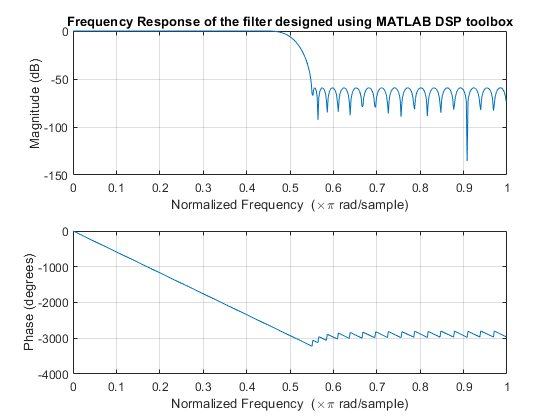

freqz(b,1);
title("Frequency Response of the filter designed using MATLAB DSP toolbox")

## Low-pass filter parameters :

disp(h)

  Columns 1 through 13

   -0.0000   -0.0011    0.0000    0.0013   -0.0000   -0.0020    0.0000    0.0029   -0.0000   -0.0041    0.0000    0.0056   -0.0000

  Columns 14 through 26

   -0.0075    0.0000    0.0100   -0.0000   -0.0131    0.0000    0.0171   -0.0000   -0.0224    0.0000    0.0299   -0.0000   -0.0411

  Columns 27 through 39

    0.0000    0.0605   -0.0000   -0.1042    0.0000    0.3177    0.5000    0.3177    0.0000   -0.1042   -0.0000    0.0605    0.0000

  Columns 40 through 52

   -0.0411   -0.0000    0.0299    0.0000   -0.0224   -0.0000    0.0171    0.0000   -0.0131   -0.0000    0.0100    0.0000   -0.0075

  Columns 53 through 65

   -0.0000    0.0056    0.0000   -0.0041   -0.0000    0.0029    0.0000   -0.0020   -0.0000    0.0013    0.0000   -0.0011   -0.0000

